[x, fs] = audioread('08-Oak B Bot-230404_1602.wav')

x =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


fs = 48000

x = x(:, 1);

N = length(x);
dt = 1/fs;
t = dt*(0:N-1);

%plot time domain signal
start = 19.4*fs

start = 9.3120e+05

stop = 20*fs

stop = 960000

signal = t(start:stop);

plot(signal, x(start:stop))

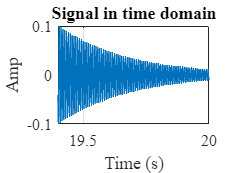

grid on
set(gca, 'FontName', 'Time New Roman', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Amp')
title('Signal in time domain')

%stats
maxValue = max(x)

maxValue = 1.0000

minValue = min(x)

minValue = -1

meanValue = mean(x)

meanValue = 3.4911e-06

stdValue = std(x)

stdValue = 0.0356

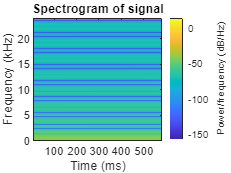

spectrogram(signal, 2048, 512, 16384, fs, 'yaxis')
title('Spectrogram of signal')